# Create and Train Network from Scratch

This script demonstrates a very simple DAG architecture and image augmentation.

You will train a network that classifies 28-by-28-by-4 images into six categories. These categories are shown in the image below:

- barren land

- building

- grassland

- road

- trees

- water

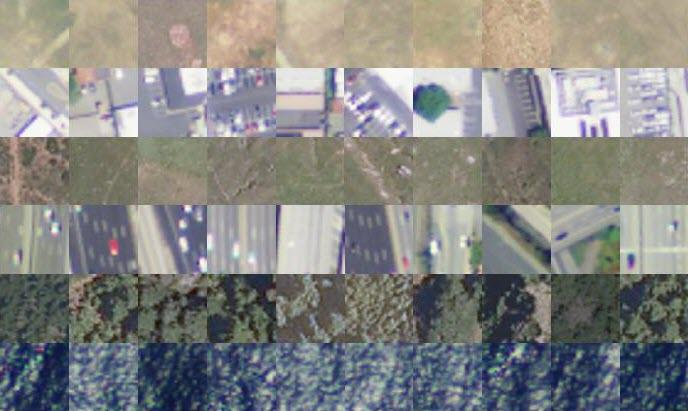

### Create layers

Notice that layers in a DAG network must have names.

layers = [
    imageInputLayer([28 28 4],'Name','input')
    
    convolution2dLayer(5,16,'Padding','same','Name','conv_1')
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')
    
    convolution2dLayer(3,32,'Padding','same','Stride',2,'Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    convolution2dLayer(3,32,'Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    
    additionLayer(2,'Name','add')
    
    averagePooling2dLayer(2,'Stride',2,'Name','avpool')
    fullyConnectedLayer(6,'Name','fc')
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classOutput')];

View layer graph.

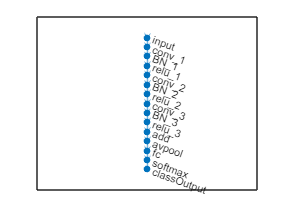

lgraph = layerGraph(layers);
plot(lgraph)

### Add shortcut connection

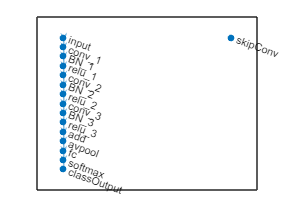

skipConv = convolution2dLayer(1,32,'Stride',2,'Name','skipConv');
lgraph = addLayers(lgraph,skipConv);
plot(lgraph)

Connect layer to rest of architecture.

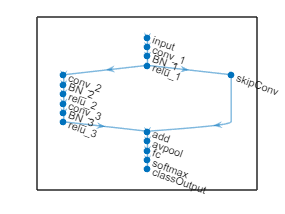

lgraph = connectLayers(lgraph,'relu_1','skipConv');
lgraph = connectLayers(lgraph,'skipConv','add/in2');
plot(lgraph);

### Augment training data

*satData.mat* includes XTrain, XTest, XVal **data**s and YTrain, YTest, YVal class **label**s

load satData.mat

imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandYReflection',true)

imageAugmenter =   imageDataAugmenter with properties:

           FillValue: 0
     RandXReflection: 1
     RandYReflection: 1
        RandRotation: [0 0]
           RandScale: [1 1]
          RandXScale: [1 1]
          RandYScale: [1 1]
          RandXShear: [0 0]
          RandYShear: [0 0]
    RandXTranslation: [0 0]
    RandYTranslation: [0 0]


augimds = augmentedImageDatastore([28 28 4],XTrain,YTrain,'DataAugmentation',imageAugmenter)

augimds =   augmentedImageDatastore with properties:

         NumObservations: 3000
           MiniBatchSize: 128
        DataAugmentation: [1×1 imageDataAugmenter]
      ColorPreprocessing: 'none'
              OutputSize: [28 28]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


### Configure training

options = trainingOptions('sgdm',...
    'MaxEpochs',60,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',20,...
    'InitialLearnRate',0.03,...
    'ValidationData',{XVal,YVal},...
    'Shuffle','every-epoch',...
    'Plots','training-progress');

### Train network

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       23.44% |       42.67% |       2.1749 |       1.4541 |          0.0300 |
|       3 |          50 |       00:00:03 |       86.72% |       84.67% |       0.2989 |       0.3947 |          0.0300 |
|       5 |         100 |       00:00:04 |       89.84% |       88.33% |       0.4443 |       0.4365 |          0.0300 |
|       7 |         150 |       00:00:05 |       90.62% |       90.17% |       0.2181 |   

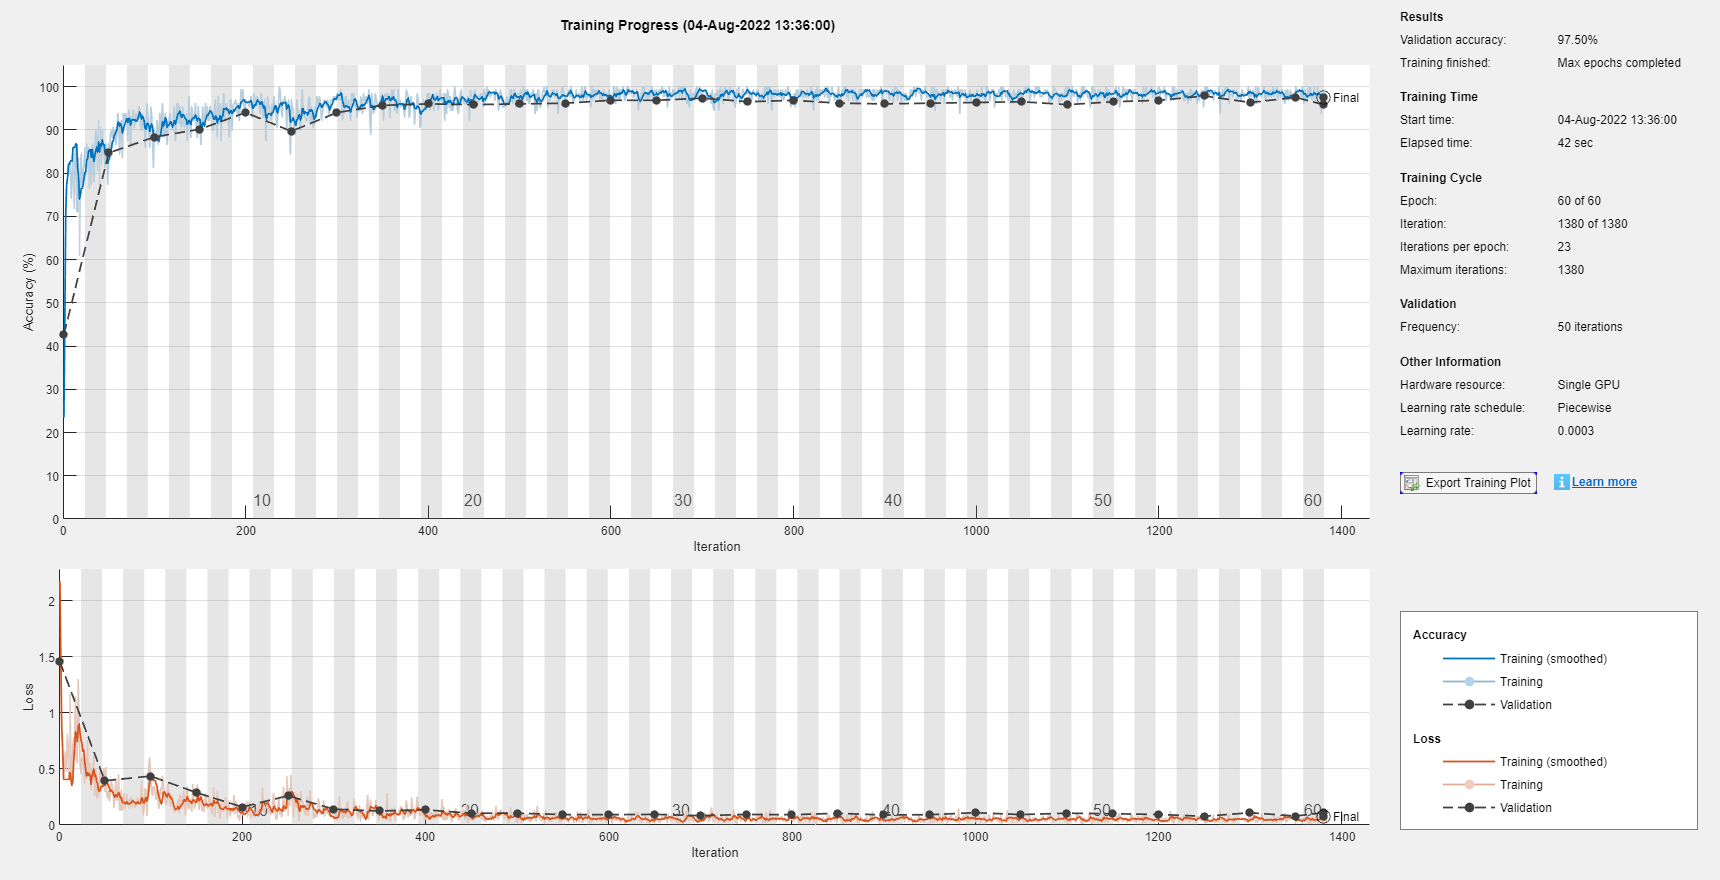

net = trainNetwork(augimds,lgraph,options);

save satdata_net net

load satdata_net.mat

### Evaluate network

testpreds = classify(net,XTest);
nnz(testpreds == YTest)/numel(testpreds)

ans = 0.9783

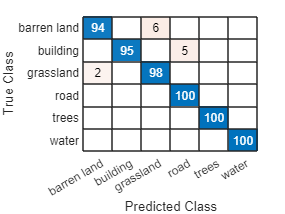


confusionchart(YTest,testpreds)